## Blind Dereverberation Exploiting the Null of Sylvester Matrix with Group Sparse Regularization in the STFT domain

clear

settings

% DGT tool
F = DGTtool("windowLength", 512, "windowShift", 128);

% audio data loading
num_piece = 2;
for i=1:num_piece
    audiofilename = "9w3r7y_01_%d";
    [temp, fs] =  audioread("input/" + sprintf(audiofilename,i)+".wav");
    ss{i} = temp(:,1);
end
s = [ss{1}; ss{2}];
num_mic = 1;

% ir data loading
[ir, ~] = audioread("BFTLSPACELIBRARY_ChamberAL_11025.wav");
%[ir, fs] = audioread("logic03sWoodenBooth8000.wav");
%[ir{2}, fs(2)] = audioread("../data/BF TL SPACE LIBRARY/Drumbrella/Drumbrella 5'.R.wav");

% ADMM settings
rho = 1.0; % ADMMのペナルティパラメータ (調整用、まずは1.0等から)
alpha = 0.02; % L1正則化の強さ (大きくするほど音漏れがゼロに潰れる)

Malloc

rt = zeros(1,1); % reverb time in sec
obs = cell(1,num_piece); % obs
X = cell(1, num_piece); % STFTs of obs. signal
S = cell(1, num_piece); % STFTs of dry signal
N = zeros(1, num_piece); % length of observation
Lir = zeros(1, 1); % ir length = d + 1
l = zeros(1, num_piece); % length of deconvoluted signal

## resample and shortening

% calculate the reverberation time (RT60)
rt = reverb_time(ir, fs);
ir = ir(1:fs); ir = ir / norm(ir);
IR = F(ir);
Lir = size(IR, 2);

for j = 1:num_piece
    obs{j} = conv(ss{j}, ir);
    X{j} = F(obs{j});
    N(j) = size(X{j}, 2);
    S{j} = F(ss{j});
end
obsCat = [obs{1}; obs{2}];
D = Lir - 1;
padding = -2;
D = D + padding;
Lir = Lir + padding;

## deconvolution in TF domain

malloc

Fq = size(X{1}, 1);
for i = 1:2, l(i) = N(1, i) - Lir(1) + 1; end
RET1 = zeros(Fq, l(1)); RET2 = zeros(Fq, l(2));
RET1W = zeros(Fq, l(1)); RET2W = zeros(Fq, l(2));
RET_slra = zeros(Fq, sum(l));
% ratio of minimum and the 2nd minimum singular value
singValRatio = zeros(Fq, 1);

% frequency-wise 

時間領域で観測 (x) がクリーン信号 (s) とIR (h) の畳み込みで表されているとする:

$\textrm{Time domain:}~{\bf x} = {\bf s} * {\bf h}$.

それらのDGT (X_f, S_f, H_f) に対して，周波数 f のサブバンドで畳み込みが近似的に成り立っているという立場をとる．


$$\textrm{TF domain}~{\bf X}_f \approx {\bf S}_f * {\bf H}_f
$$


今，独立な二つのクリーン信号 s^1, s^2 があって，同一のIRが畳み込まれたものを観測しているとする:

$\textrm{Time domain} : {\bf x}^{1} = {\bf s}^1 * {\bf h}, {\bf x}^2 = {\bf s}^2* {\bf h}$.

TF領域では，それに対応して


$$\textrm{TF domain} : {\bf X}^{1}_f = {\bf S}^1_f * {\bf H}_f, {\bf X}^2_f = {\bf S}^2_f* {\bf H}_f$$


がある．式をいじって，次を得る:

$\textrm{TF domain} : {\bf X}^{1}_f * {\bf S}_f^2 = {\bf X}^2_f * {\bf S}^1_f,= {\bf S}_f^1*{\bf S}^2_f* {\bf H}_f$.

一つ目の等号の部分から


$$\textrm{TF domain} : {\bf X}^{1}_f * {\bf S}_f^2 - {\bf X}^2_f * {\bf S}^1_f = {\bf 0}$$


これを畳み込み行列を使って表すと，


$$\textrm{TF domain} : \\
{\rm Conv}({\bf X}^{1}_f) {\bf S}_f^2 - {\rm Conv}({\bf X}^2_f) {\bf S}^1_f = {\bf 0}\\ \downarrow\\
\left[{\rm Conv}({\bf X}^{2}_f)  ~{\rm Conv}(-{\bf X}^1_f)\right]
\left[\begin{array}{c}{ {\bf S}^1_f \\{\bf S}_f^2\end{array}\right]= {\bf 0}
$$


（最後に出てきた式の係数行列はSylvester行列と名前がついている）


$${\rm Sylvester} \overset{\rm def}{=} \left[{\rm Conv}({\bf X}^{2}_f)  ~{\rm Conv}(-{\bf X}^1_f)\right]$$


Sylvester行列の零空間の基底ベクトルとしてクリーン信号S_f^1, S_f^2 を獲得する．

TF領域での「近似」畳み込みモデルを使っているので，上記のSylvester行列はフルランク行列になってしまっている，

つまり零空間はないのだが，その代わりに最小特異値に対応する右特異ベクトルを使用してクリーン信号の復元を試みる．

parfor f = 1:Fq
    temp = X{1, 1};  X1f = temp(f, :)';
    temp = X{1, 2};  X2f = temp(f, :)';
    [v1, v2] = sylDerevl21_loc(X1f, X2f, l, rho, alpha);
    RET1(f,:) = v1';   RET2(f,:) = v2';
    % RET1W(f,:) = Vf_w(1:l(1))'; RET2W(f,:) = Vf_w(l(1)+1:end)';
end

Alignment in Time domain

retMid{1} = F.pinv(RET1);   retMid{2} = F.pinv(RET2);
extract_samples_obs = min(22050, length(retMid{1}));
extract_samples = 22050 - length(ir) + 1;
idx_short = 1 : extract_samples_obs;

s1_short = retMid{1}(1:extract_samples);
s2_short = retMid{2}(1:extract_samples);
obs1_short = obs{1}(idx_short);
obs2_short = obs{2}(idx_short);

% ③ 小さなサイズでToeplitz行列を作成（これなら数秒で終わります）
A_time = [convmtx(s1_short, length(ir)); convmtx(s2_short, length(ir))];
b_time = [obs1_short; obs2_short];

% ④ 時間領域での最小二乗法（因果性を保ったままIRを抽出）
% 雑音対策として、ほんのわずかに正則化（Diagonal Loading）を入れておくとさらに安定します
reg = 1e-4 * max(abs(A_time(:)));
h_time = (A_time' * A_time + reg * eye(size(A_time, 2))) \ (A_time' * b_time);

% ⑤ 抽出した共通IR（h_time）をSTFTの窓長に合わせてFFT
H_stft_domain = fft(h_time, F.FFTnum); 

% ⑥ STFTの各周波数ビンに対して「逆方向の位相回転」を一括適用
for f = 1:Fq
    if abs(H_stft_domain(f)) > 1e-12
        % 位相を取得
        phase_correction_f = H_stft_domain(f) / abs(H_stft_domain(f));
        
        % 【重要】クリーン信号側は「共役複素数（逆方向）」に回す
        RET1(f,:) = RET1(f,:) .* conj(phase_correction_f);
        RET2(f,:) = RET2(f,:) .* conj(phase_correction_f);
    end
end

% ⑦ 最終的な残響除去音声の出力
ret{1} = F.pinv(RET1);
ret{2} = F.pinv(RET2);


Display


for i=1:2
    len_ss = length(ss{i});
    len_ret = length(ret{i});
    if len_ss > len_ret
        ss{i} = ss{i}(1:len_ret);
        len_ss = len_ret;
    end
    [SDR,SIR,SAR,perm] = bss_eval_sources(obs{i}(1:len_ss)', ss{i}');
    fprintf("obs: SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    [SDR,SIR,SAR,perm] = bss_eval_sources(retMid{i}(1:len_ss)', ss{i}');
    fprintf("ret(mid): SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    [SDR,SIR,SAR,perm] = bss_eval_sources(ret{i}(1:len_ss)', ss{i}');
    fprintf("ret: SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    audiowrite("output/" + sprintf(audiofilename +"_wet.wav", i), obs{i}, fs)
    audiowrite("output/" + sprintf(audiofilename +"_lra_ORACLE_pad=%d.wav", i, padding), ret{i}, fs)
    % audiowrite("output/" + sprintf(audiofilename +"_lra_ORACLE(w)_pad=%d.wav", i, padding), ret_w{i}, fs)
    % audiowrite("output/slra.wav", ret_slra, fs)
end

obs: SDR 0.689, SIR Inf, SAR 0.689


ret(mid): SDR 9.827, SIR Inf, SAR 9.827


ret: SDR 9.261, SIR Inf, SAR 9.261


obs: SDR -0.120, SIR Inf, SAR -0.120


ret(mid): SDR 7.226, SIR Inf, SAR 7.226


ret: SDR 8.556, SIR Inf, SAR 8.556


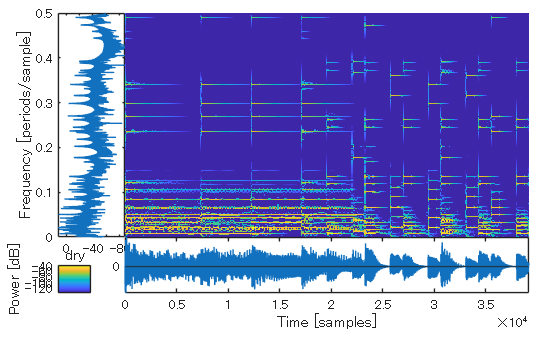


F.plotReassign(ss{1});title("dry"); 
saveas(gcf, "result/" + sprintf(audiofilename,1) + "_dry.png")

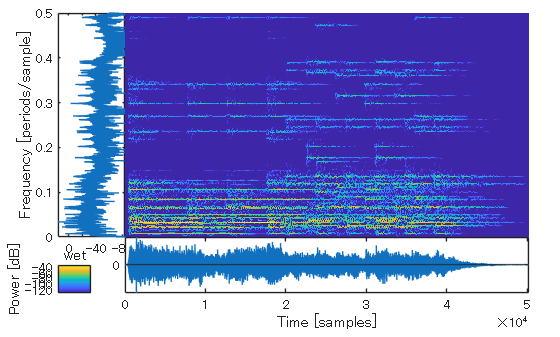

F.plotReassign(obs{1}); title("wet"); 
saveas(gcf, "result/" + sprintf(audiofilename,1) + "_wet.png")

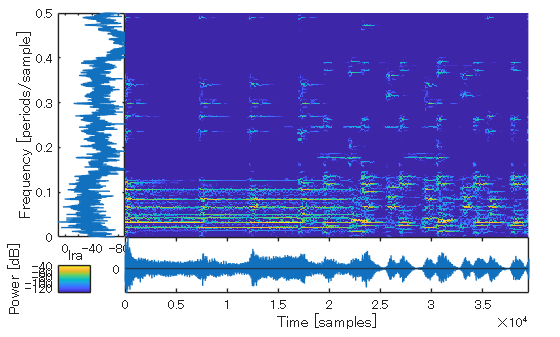

F.plotReassign(ret{1}); title("lra");
saveas(gcf, "result/" + sprintf(audiofilename + "_ORACLE_ret_pad=%d.png",1, padding) )

- どの結果も時間のマイナス方向に信号が漏れ出ているのがきになる．

- weight をいれることで若干改善．ただ，きいてもわからない

function [v1, v2, info] = sylDerevl21_loc(X1f, X2f, l, rho, alpha)
Xf = [X1f; X2f];
XfNorm = norm(Xf);   XfPhase = Xf ./ abs(Xf);

% Null-space calculation via (not structured) low-rank approximation
Sylvester = [convmtx(X2f, l(1)) convmtx(-X1f, l(2))];
[~, Sigma, V] = svd(Sylvester, "econ");
% Sigma = diag(Sigma);
% singValRatio(f) = Sigma(end) / Sigma(end-1);

% 事前準備 (ループの外で1回だけ計算できるので高速)
AtA = Sylvester' * Sylvester;

% ★現在のTikhonovのコードとほぼ同じ逆行列を事前計算！
% InvMatrix = inv(AtA + rho * eye(size(AtA)));
decompAtA = decomposition(AtA + rho * eye(size(AtA)));

% 変数の初期化
u_init = V(:, end); % 現在成功しているSVDの解（これをベースにする）
u = u_init;
z = u_init;         % ★ zを0ではなく、現在のSVDの解で初期化する
y = zeros(size(u)); % 乗数は0でOK

% --- グループ（インデックス）の定義 (例: 4要素ずつを1グループとする) ---
% 変数のサイズに応じて適切にグループを分割してください
group_size = 4;
num_elements = length(u);
num_groups = ceil(num_elements / group_size);

for iter = 1:20
    % 1. u-update (前回と同様)
    % u = InvMatrix * (rho * z - y);
    u = decompAtA \ (rho * z - y);

    % 2. z-update (Block Soft-Thresholding)
    v = u + y / rho;
    z = zeros(size(v)); % 詰め替え用のバッファ

    for g = 1:num_groups
        % 各グループのインデックスを抽出
        idx = ((g-1)*group_size + 1) : min(g*group_size, num_elements);
        v_g = v(idx);

        % グループの L2 ノルム（エネルギー）を計算
        norm_vg = norm(v_g, 2);

        % Block Soft-Thresholding の適用
        if norm_vg > (alpha / rho)
            % グループ内の全要素を、共通の縮小係数でスケールダウン（スパースにしない）
            z(idx) = v_g * (1 - (alpha / rho) / norm_vg);
        else
            % グループのエネルギーが閾値以下なら、グループ丸ごとゼロにする
            z(idx) = 0;
        end
    end

    % ゼロ除算対策および全体正規化
    if norm(z) < 1e-12
        z = u_init;
    else
        z = z / norm(z);
    end

    % 3. y-update (前回と同様)
    y = y + rho * (u - z);
end

% 最終的なクリーン信号の推定値として z を使用する
Vf = z;
Vf = XfNorm * Vf / norm(Vf); % scale recovery
VfAng = angle(Vf);

% % subband IR estimation
% A = [convmtx(Vf(1:l(1)), L(1)); convmtx(Vf(l(1)+1:end), L(1))];     b = [X1f; X2f];
% Hhat = A \ b; % calc. IR (TF domain)
% HhatPhase = Hhat / abs(Hhat);
% [Hhatmax, idx_HhatPeak] = max(abs(Hhat));


% Regularization on the phase rotation of Vf
Vf_avephase = Vf; % / Hhatmax;

v1 = Vf_avephase(1:l(1));
v2 = Vf_avephase(l(1)+1:end);
end